## *C. elegans* length measurements comparison between WorMe and manually obtained with Fiji ImageJ, applying the manual bias error in WorMe.

In this little experiment we check if the measures between manually obtained by Fiji and automatically obtained with WorMe have the same means.

We have data of three different *C. elegans* sets of images: C24, C48 and C72. Every set is different time of development of *C. elegans*, and different images characteristics.

In the study we show the measurements obtained from **WorMe applying the manual bias error** is the same than the measurements obtained manually from the ImageJ. The manual bias error is actioned when despite of obtain the length from the euclidean distance between every pixel in the skeletonized line of C. elegans, we obtain this length every 5 pixels, emulating the manual polyline measurement.

First, we study the normality of the data, and then we visualize boxplot and histogram between every set of sample (C24, C48 and C72), between the measurement automatiacally by WorMe and the measurement obtained manually by imageJ.

dades_cru = readtable("C:\Users\jubet\Desktop\Data_comparison.ods")

dades_cru = 57×6 table
    C24_Fiji    C48_Fiji    C72_Fiji    C24_WM    C48_WM    C72_WM
    ________    ________    ________    ______    ______    ______

     399.06      729.85      954.23     259.31    795.23    1093.6
      338.1      703.34      895.65     236.14    726.89     956.9
     474.77      663.11      1011.8     368.66    785.15    875.45
     348.25      753.32      1120.3     429.23    732.71    1022.7
     365.26      607.73      1037.8     367.33    713.76    1092.4
     335.09      903.59      1162.5     309.29    695.96    1012.8
     371.87       696.2      1199.7     397.47    693.71    1128.8
     387.62      709.86      986.51     491.72    628.93    1174.6
     466.08      727.41      1023.6     327.37    851.97    989.23
     415.06       735.8      1092.3

propietats_dades_cru = dades_cru.Properties.VariableNames

propietats_dades_cru = 1×6 cell array
    {'C24_Fiji'}    {'C48_Fiji'}    {'C72_Fiji'}    {'C24_WM'}    {'C48_WM'}    {'C72_WM'}


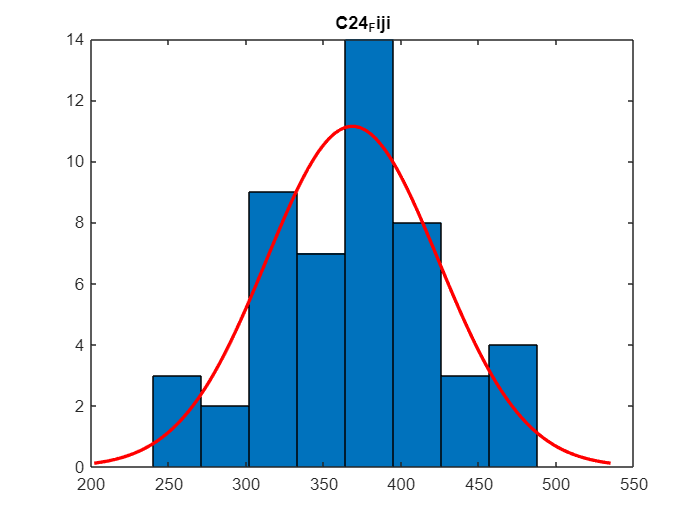

Shapiro test: There is NO normality. p-val: 0.75503


descript_dades_sing = 7×1 table
                      C24_Fiji
                      ________

    mean               368.49 
    std                55.473 
    n                      50 
    Std error mean     7.8451 
    Max                480.01 
    Min                247.59 
    Range              232.42 


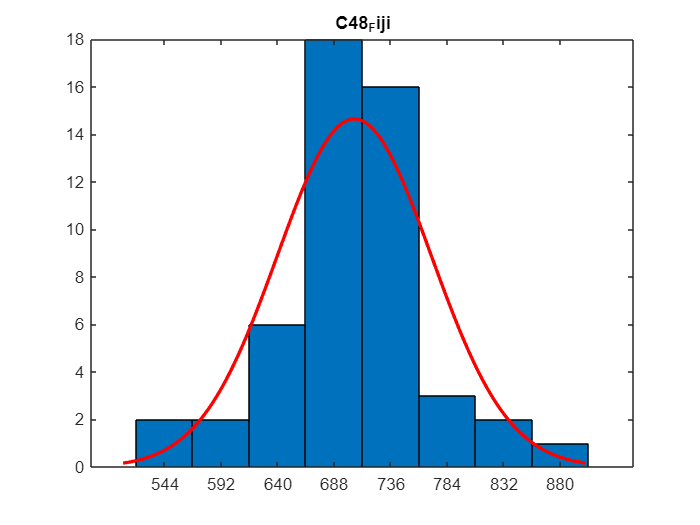

Shapiro test: There is normality. p-val: 0.028553


descript_dades_sing = 7×1 table
                      C48_Fiji
                      ________

    mean               705.05 
    std                65.395 
    n                      50 
    Std error mean     9.2482 
    Max                903.59 
    Min                532.49 
    Range               371.1 


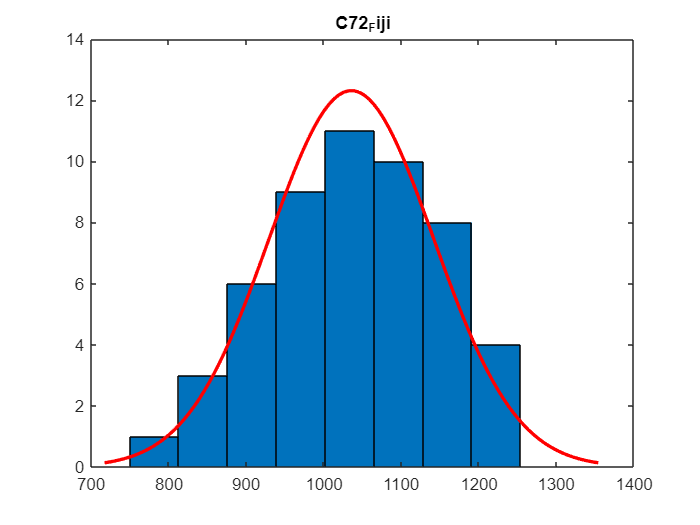

Shapiro test: There is NO normality. p-val: 0.67909


descript_dades_sing = 7×1 table
                      C72_Fiji
                      ________

    mean               1035.5 
    std                106.14 
    n                      52 
    Std error mean     14.719 
    Max                1247.1 
    Min                 799.8 
    Range              447.26 


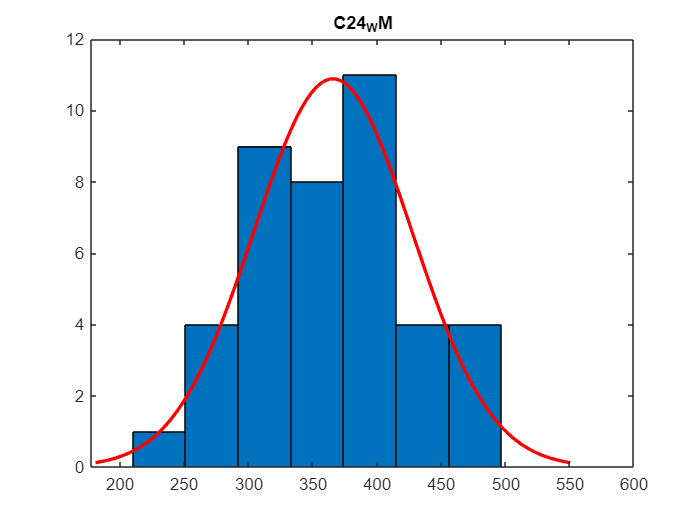

Shapiro test: There is NO normality. p-val: 0.87855


descript_dades_sing = 7×1 table
                      C24_WM
                      ______

    mean              365.55
    std                61.61
    n                     41
    Std error mean    9.6218
    Max               491.72
    Min               236.14
    Range             255.58


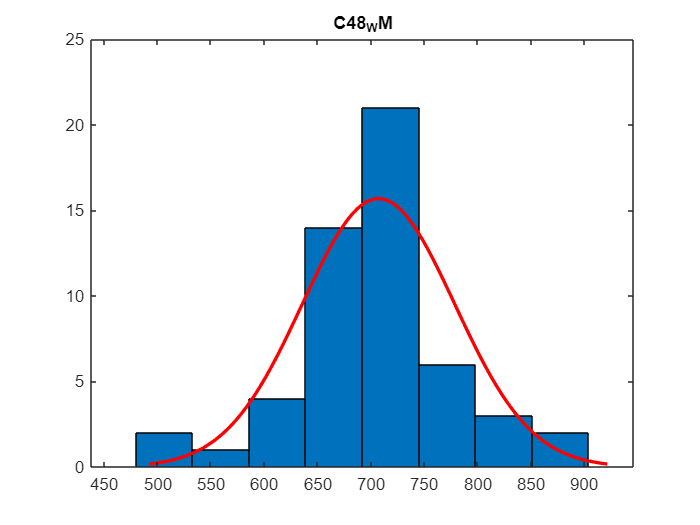

Shapiro test: There is normality. p-val: 0.037411


descript_dades_sing = 7×1 table
                      C48_WM
                      ______

    mean              707.01
    std               71.471
    n                     53
    Std error mean    9.8173
    Max               902.02
    Min               517.09
    Range             384.93


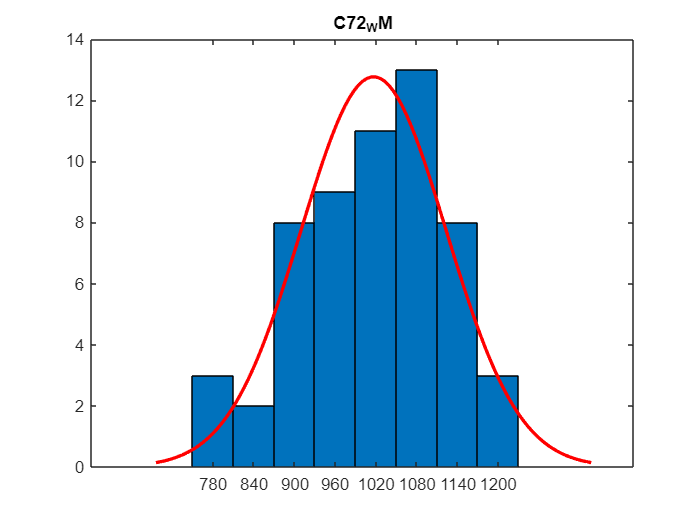

Shapiro test: There is NO normality. p-val: 0.23794


descript_dades_sing = 7×1 table
                      C72_WM
                      ______

    mean              1016.3
    std               106.89
    n                     57
    Std error mean    14.158
    Max                 1229
    Min               791.37
    Range             437.59



descript_dades_total = [];
for variable_n = propietats_dades_cru

    variable_name = variable_n{1};

    dades_cru_singular = dades_cru{:,variable_name};

    % Treiem els NaN
    dades_cru_singular = dades_cru_singular(~isnan(dades_cru_singular));

    % Histfit
    figure; histfit(dades_cru_singular); hold on; title(variable_name); hold off;

%     % Probem normalitat
%     [ktest_res, p_val_ktest] = kstest(dades_cru_singular);

    % Shapiro test
    [shaptest, pValue, W] = swtest(dades_cru_singular); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest
        disp(strcat("Shapiro test: There is normality. p-val: ", string(pValue)))
    else
        disp(strcat("Shapiro test: There is NO normality. p-val: ", string(pValue)))
    end

    % Estadística descriptiva
    descript_dades = {mean(dades_cru_singular); std(dades_cru_singular); ...
        numel(dades_cru_singular); ...
        std(dades_cru_singular) / sqrt(numel(dades_cru_singular)); ...
        max(dades_cru_singular); ...
        min(dades_cru_singular); ...
        max(dades_cru_singular) - min(dades_cru_singular)};

    descript_dades_sing = cell2table(descript_dades, 'VariableNames',variable_n, 'RowNames',["mean", "std", "n", "Std error mean", "Max", "Min", "Range"])

    if isempty(descript_dades_total)
        descript_dades_total = descript_dades_sing;
    else
        descript_dades_total = [descript_dades_total, descript_dades_sing];


    end
end


% Taula estadística descriptiva total:
descript_dades_total

descript_dades_total = 7×6 table
                      C24_Fiji    C48_Fiji    C72_Fiji    C24_WM    C48_WM    C72_WM
                      ________    ________    ________    ______    ______    ______

    mean               368.49      705.05      1035.5     365.55    707.01    1016.3
    std                55.473      65.395      106.14      61.61    71.471    106.89
    n                      50          50          52         41        53        57
    Std error mean     7.8451      9.2482      14.719     9.6218    9.8173    14.158
    Max                480.01      903.59      1247.1     491.72    902.02      1229
    Min                247.59      532.49       799.8     236.14 


[array_dades_tot, array_repetits_categories_categorical] = fer_boxplot_from_taula(dades_cru)

array_dades_tot = 	1.0e+03 *

    0.3991    0.3381    0.4748    0.3483    0.3653    0.3351    0.3719    0.3876    0.4661    0.4151    0.3523    0.3304    0.3952    0.3755    0.4677    0.3410    0.4272    0.4058    0.2834    0.3781    0.3801    0.3582    0.3069    0.4172    0.3950    0.3697    0.4298    0.3677    0.3039    0.3859    0.4800    0.3293    0.3827    0.3681    0.3114    0.3557    0.3228    0.3269    0.4174    0.3854    0.4145    0.3779    0.4171    0.3275    0.2986    0.2579    0.4516    0.2476    0.2573    0.3227


array_repetits_categories_categorical = 1×303 categorical array
     C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C24_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fiji      C48_Fij

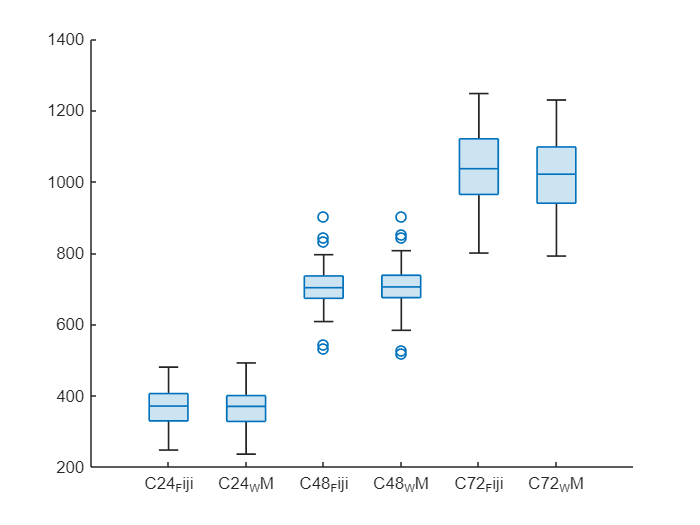

boxchart(array_repetits_categories_categorical, array_dades_tot)

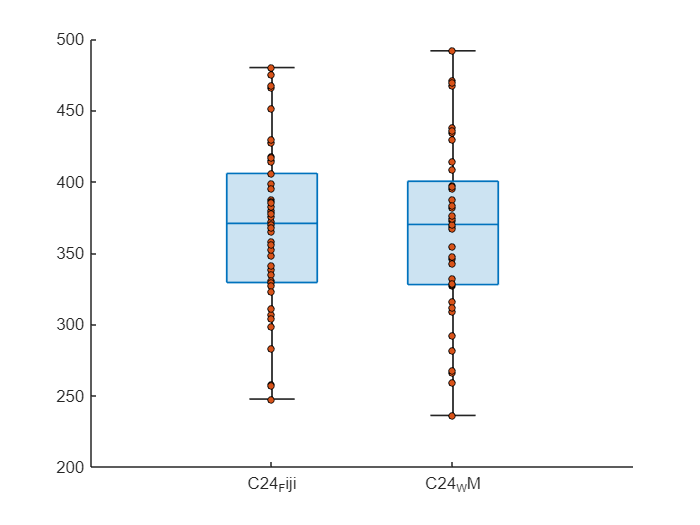

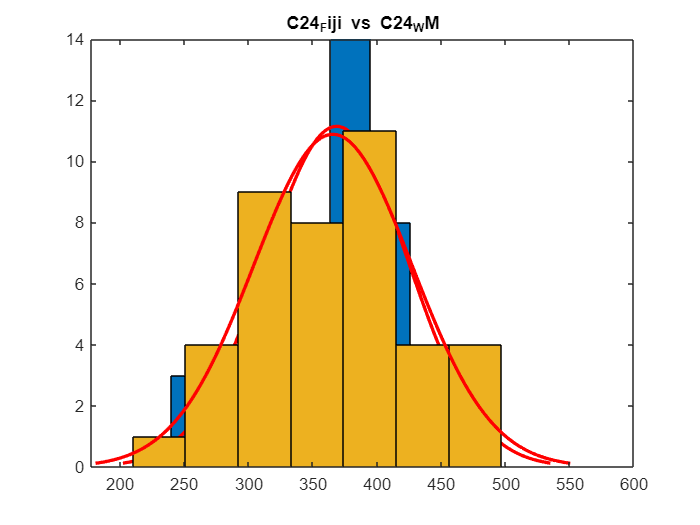

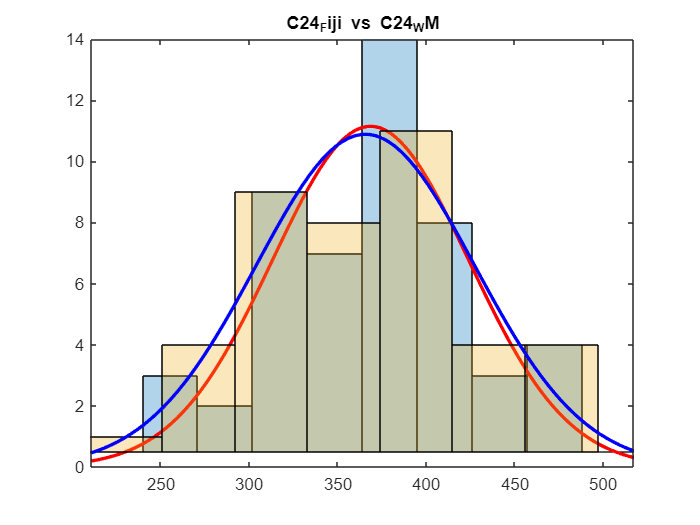

descript_dades_sing_tot = 7×2 table
                      C24_Fiji    C24_WM
                      ________    ______

    mean               368.49     365.55
    std                55.473      61.61
    n                      50         41
    Std error mean     7.8451     9.6218
    Max                480.01     491.72
    Min                247.59     236.14
    Range              232.42     255.58


C24_Fiji: Shapiro test: There is NO normality. p-val: 0.75503


C24_WM: Shapiro test: There is NO normality. p-val: 0.87855


Wilcoxon test


Wilcoxon test: Non-Reject H0: samples have same means. p-val: 0.83882


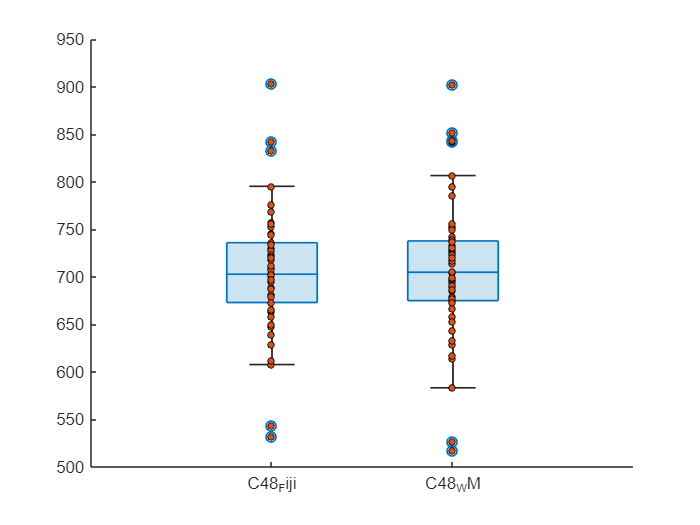

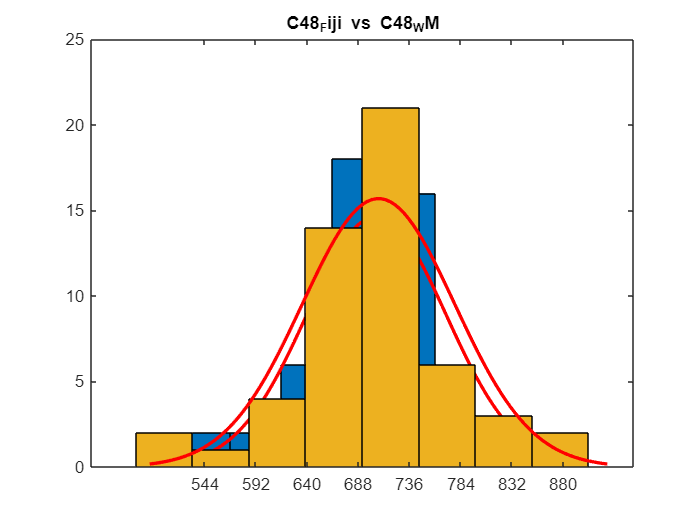

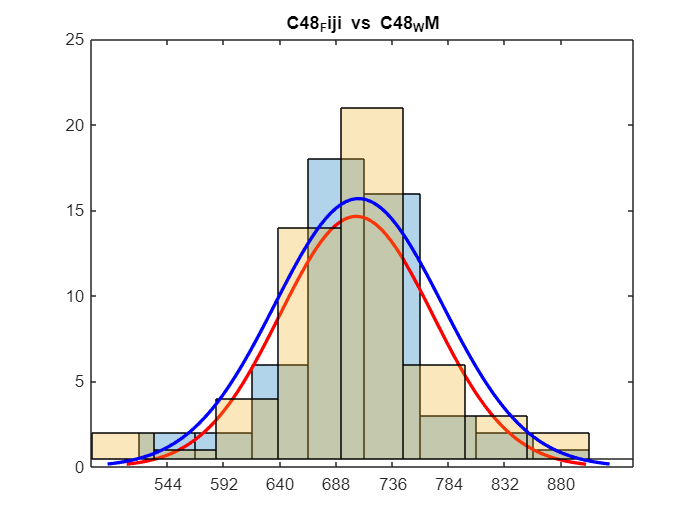

descript_dades_sing_tot = 7×2 table
                      C48_Fiji    C48_WM
                      ________    ______

    mean               705.05     707.01
    std                65.395     71.471
    n                      50         53
    Std error mean     9.2482     9.8173
    Max                903.59     902.02
    Min                532.49     517.09
    Range               371.1     384.93


C48_Fiji: Shapiro test: There is normality. p-val: 0.028553


C48_WM: Shapiro test: There is normality. p-val: 0.037411


Shapiro test


T-test: Not reject H0: samples have same means. p-val: 0.88549


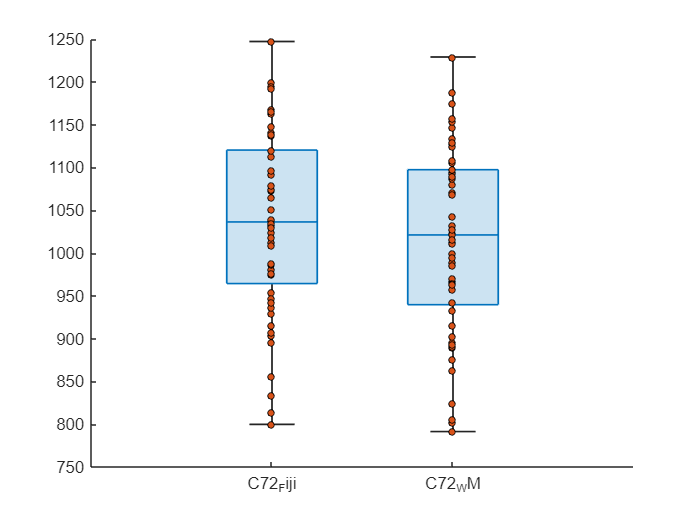

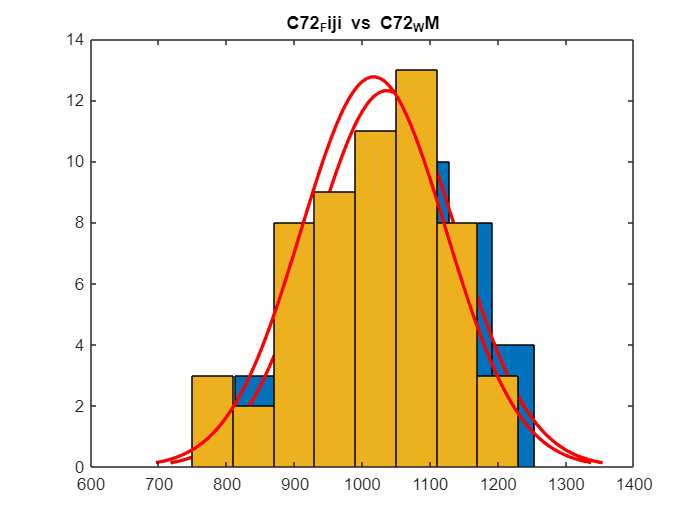

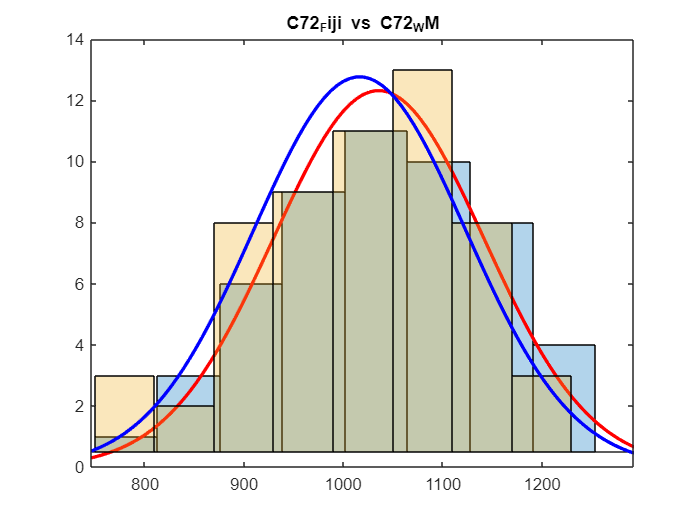

descript_dades_sing_tot = 7×2 table
                      C72_Fiji    C72_WM
                      ________    ______

    mean               1035.5     1016.3
    std                106.14     106.89
    n                      52         57
    Std error mean     14.719     14.158
    Max                1247.1       1229
    Min                 799.8     791.37
    Range              447.26     437.59


C72_Fiji: Shapiro test: There is NO normality. p-val: 0.67909


C72_WM: Shapiro test: There is NO normality. p-val: 0.23794


Wilcoxon test


Wilcoxon test: Non-Reject H0: samples have same means. p-val: 0.35173




for n_var = 1:3
    % Taula temporal
    dades_cru_t = dades_cru(:,[n_var,n_var+3]);

    % Operacio obtenir boxplot
    [array_dades_tot, array_repetits_categories_categorical] = fer_boxplot_from_taula(dades_cru_t);


    % Graficació boxplot
    figure; boxchart(array_repetits_categories_categorical, array_dades_tot);
    hold on
    scatter(array_repetits_categories_categorical, array_dades_tot, 15, 'filled', 'MarkerEdgeColor', [0 0 0])
    hold off

    % Comparacio entre els dos:
    variable_names_sing = dades_cru_t.Properties.VariableNames;

    variable_names_sing_1 = variable_names_sing{1};
    variable_names_sing_2 = variable_names_sing{2};
%     dades_cru_sing1 = dades_cru(:,[n_var]);
%     dades_cru_sing2 = dades_cru(:,[n_var+3]);

    dades_cru_sing1 = dades_cru{:,variable_names_sing_1};
    dades_cru_sing2 = dades_cru{:,variable_names_sing_2};

    % Treiem NaN:
    dades_cru_sing1 = dades_cru_sing1(~isnan(dades_cru_sing1));
    dades_cru_sing2 = dades_cru_sing2(~isnan(dades_cru_sing2));


    % __Descripció hisfit__

    nom_titol = strcat(variable_names_sing_1, " vs ", variable_names_sing_2);

    % __Descripció hisfit 1__
    figure
    histfit(dades_cru_sing1); hold on; histfit(dades_cru_sing2); 
    title(nom_titol);
    hold off

    % __Descripció hisfit 2__
    % Definim punts minims i maxims de la grafica
    punt_min = min([dades_cru_sing1; dades_cru_sing2]);
    punt_max = max([dades_cru_sing1; dades_cru_sing2]);

    % Rang ( per a definir lim x)
    rangminmax = punt_max - punt_min;
    rangminmax_lim = rangminmax * 0.1;

    figure
    h1 = histfit(dades_cru_sing1);
    set(gca, 'XLim', [punt_min-rangminmax_lim  punt_max+rangminmax_lim])
    h1(1).BaseValue = 0.5;
    h1(1).FaceAlpha = 0.3;
    hold on
    h2 = histfit(dades_cru_sing2);
    h2(1).BaseValue = 0.5;
    h2(1).FaceAlpha = 0.3;
    h2(2).Color = "blue";
    title(nom_titol)

    %legend([h1 h2], variable_names_sing_1, variable_names_sing_2)

    hold off



    % Descripció dades estadística descriptiva:
    % Estadística descriptiva dades 1
    descript_dades = {mean(dades_cru_sing1); std(dades_cru_sing1); ...
        numel(dades_cru_sing1); ...
        std(dades_cru_sing1) / sqrt(numel(dades_cru_sing1)); ...
        max(dades_cru_sing1); ...
        min(dades_cru_sing1); ...
        max(dades_cru_sing1) - min(dades_cru_sing1)};

    descript_dades_sing_1 = cell2table(descript_dades, 'VariableNames', {variable_names_sing_1}, 'RowNames', ["mean", "std", "n", "Std error mean", "Max", "Min", "Range"]);


        % Estadística descriptiva dades 2
    descript_dades = {mean(dades_cru_sing2); std(dades_cru_sing2); ...
        numel(dades_cru_sing2); ...
        std(dades_cru_sing2) / sqrt(numel(dades_cru_sing2)); ...
        max(dades_cru_sing2); ...
        min(dades_cru_sing2); ...
        max(dades_cru_sing2) - min(dades_cru_sing2)};

    descript_dades_sing_2 = cell2table(descript_dades, 'VariableNames',{variable_names_sing_2}, 'RowNames',["mean", "std", "n", "Std error mean", "Max", "Min", "Range"]);
    
descript_dades_sing_tot = [descript_dades_sing_1, descript_dades_sing_2]



% ___Comparació de dades___


    % _Determinació normalitat_
    
    % Shapiro test 1
    [shaptest_1, pValue_1, W] = swtest(dades_cru_sing1); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest_1
        disp(strcat(variable_names_sing_1, ": Shapiro test: There is normality. p-val: ", string(pValue_1)))
    else
        disp(strcat(variable_names_sing_1, ": Shapiro test: There is NO normality. p-val: ", string(pValue_1)))
    end



    % Shapiro test 2
    [shaptest_2, pValue_2, W] = swtest(dades_cru_sing2); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest_2
        disp(strcat(variable_names_sing_2, ": Shapiro test: There is normality. p-val: ", string(pValue_2)))
    else
        disp(strcat(variable_names_sing_2, ": Shapiro test: There is NO normality. p-val: ", string(pValue_2)))
    end
        
    % Si hi ha normalitat en les dades: Shapiro test
    if shaptest_1 && shaptest_1
        % Si hi ha normalitat: unpaired t test
        disp("Shapiro test")
        [ttest_result, ttest_p] = ttest2(dades_cru_sing1, dades_cru_sing2);
    
        % Test the null hypothesis that the two data samples are from populations with equal means
        % ttest_result = 0: Not reject H0 : Igual mitjanes
    
        if ~ttest_result
            disp(strcat("T-test: Not reject H0: samples have same means. p-val: ", string(ttest_p)))
        else
            disp(strcat("T-test: Reject H0: samples have different means. p-val: ", string(ttest_p)))
        end
    
    else
    % Si no hi ha normalitat: suma de rangos de Wilcoxon
        disp("Wilcoxon test")
        [wilcox_pval, wilcox_result] = ranksum(dades_cru_sing1, dades_cru_sing2);
    
        % H0: Equal medians
        % wilcox_result = 1:  rejection of the null hypothesis: Different means.
    
        if ~wilcox_result
            disp(strcat("Wilcoxon test: Non-Reject H0: samples have same means. p-val: ", string(wilcox_pval)))
        else
            disp(strcat("Wilcoxon test: Reject H0: samples have different means. p-val: ", string(wilcox_pval)))
        end
    
    
    
    end    

end

%Function of Shapiro-Wilk test from: https://es.mathworks.com/matlabcentral/fileexchange/13964-shapiro-wilk-and-shapiro-francia-normality-tests

function [H, pValue, W] = swtest(x, alpha)
%SWTEST Shapiro-Wilk parametric hypothesis test of composite normality.
%   [H, pValue, SWstatistic] = SWTEST(X, ALPHA) performs the
%   Shapiro-Wilk test to determine if the null hypothesis of
%   composite normality is a reasonable assumption regarding the
%   population distribution of a random sample X. The desired significance 
%   level, ALPHA, is an optional scalar input (default = 0.05).
%
%   The Shapiro-Wilk and Shapiro-Francia null hypothesis is: 
%   "X is normal with unspecified mean and variance."
%
%   This is an omnibus test, and is generally considered relatively
%   powerful against a variety of alternatives.
%   Shapiro-Wilk test is better than the Shapiro-Francia test for
%   Platykurtic sample. Conversely, Shapiro-Francia test is better than the
%   Shapiro-Wilk test for Leptokurtic samples.
%
%   When the series 'X' is Leptokurtic, SWTEST performs the Shapiro-Francia
%   test, else (series 'X' is Platykurtic) SWTEST performs the
%   Shapiro-Wilk test.
% 
%    [H, pValue, SWstatistic] = SWTEST(X, ALPHA)
%
% Inputs:
%   X - a vector of deviates from an unknown distribution. The observation
%     number must exceed 3 and less than 5000.
%
% Optional inputs:
%   ALPHA - The significance level for the test (default = 0.05).
%  
% Outputs:
%  SWstatistic - The test statistic (non normalized).
%
%   pValue - is the p-value, or the probability of observing the given
%     result by chance given that the null hypothesis is true. Small values
%     of pValue cast doubt on the validity of the null hypothesis.
%
%     H = 0 => Do not reject the null hypothesis at significance level ALPHA.
%     H = 1 => Reject the null hypothesis at significance level ALPHA.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                Copyright (c) 17 March 2009 by Ahmed Ben Saïda          %
%                 Department of Finance, IHEC Sousse - Tunisia           %
%                       Email: ahmedbensaida@yahoo.com                   %
%                    $ Revision 3.0 $ Date: 18 Juin 2014 $               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%
% References:
%
% - Royston P. "Remark AS R94", Applied Statistics (1995), Vol. 44,
%   No. 4, pp. 547-551.
%   AS R94 -- calculates Shapiro-Wilk normality test and P-value
%   for sample sizes 3 <= n <= 5000. Handles censored or uncensored data.
%   Corrects AS 181, which was found to be inaccurate for n > 50.
%   Subroutine can be found at: http://lib.stat.cmu.edu/apstat/R94
%
% - Royston P. "A pocket-calculator algorithm for the Shapiro-Francia test
%   for non-normality: An application to medicine", Statistics in Medecine
%   (1993a), Vol. 12, pp. 181-184.
%
% - Royston P. "A Toolkit for Testing Non-Normality in Complete and
%   Censored Samples", Journal of the Royal Statistical Society Series D
%   (1993b), Vol. 42, No. 1, pp. 37-43.
%
% - Royston P. "Approximating the Shapiro-Wilk W-test for non-normality",
%   Statistics and Computing (1992), Vol. 2, pp. 117-119.
%
% - Royston P. "An Extension of Shapiro and Wilk's W Test for Normality
%   to Large Samples", Journal of the Royal Statistical Society Series C
%   (1982a), Vol. 31, No. 2, pp. 115-124.
%

%
% Ensure the sample data is a VECTOR.
%

if numel(x) == length(x)
    x  =  x(:);               % Ensure a column vector.
else
    error(' Input sample ''X'' must be a vector.');
end

%
% Remove missing observations indicated by NaN's and check sample size.
%

x  =  x(~isnan(x));

if length(x) < 3
   error(' Sample vector ''X'' must have at least 3 valid observations.');
end

if length(x) > 5000
    warning('Shapiro-Wilk test might be inaccurate due to large sample size ( > 5000).');
end

%
% Ensure the significance level, ALPHA, is a 
% scalar, and set default if necessary.
%

if (nargin >= 2) && ~isempty(alpha)
   if ~isscalar(alpha)
      error(' Significance level ''Alpha'' must be a scalar.');
   end
   if (alpha <= 0 || alpha >= 1)
      error(' Significance level ''Alpha'' must be between 0 and 1.'); 
   end
else
   alpha  =  0.05;
end

% First, calculate the a's for weights as a function of the m's
% See Royston (1992, p. 117) and Royston (1993b, p. 38) for details
% in the approximation.

x       =   sort(x); % Sort the vector X in ascending order.
n       =   length(x);
mtilde  =   norminv(((1:n)' - 3/8) / (n + 1/4));
weights =   zeros(n,1); % Preallocate the weights.

if kurtosis(x) > 3
    
    % The Shapiro-Francia test is better for leptokurtic samples.
    
    weights =   1/sqrt(mtilde'*mtilde) * mtilde;

    %
    % The Shapiro-Francia statistic W' is calculated to avoid excessive
    % rounding errors for W' close to 1 (a potential problem in very
    % large samples).
    %

    W   =   (weights' * x)^2 / ((x - mean(x))' * (x - mean(x)));

    % Royston (1993a, p. 183):
    nu      =   log(n);
    u1      =   log(nu) - nu;
    u2      =   log(nu) + 2/nu;
    mu      =   -1.2725 + (1.0521 * u1);
    sigma   =   1.0308 - (0.26758 * u2);

    newSFstatistic  =   log(1 - W);

    %
    % Compute the normalized Shapiro-Francia statistic and its p-value.
    %

    NormalSFstatistic =   (newSFstatistic - mu) / sigma;
    
    % Computes the p-value, Royston (1993a, p. 183).
    pValue   =   1 - normcdf(NormalSFstatistic, 0, 1);
    
else
    
    % The Shapiro-Wilk test is better for platykurtic samples.

    c    =   1/sqrt(mtilde'*mtilde) * mtilde;
    u    =   1/sqrt(n);

    % Royston (1992, p. 117) and Royston (1993b, p. 38):
    PolyCoef_1   =   [-2.706056 , 4.434685 , -2.071190 , -0.147981 , 0.221157 , c(n)];
    PolyCoef_2   =   [-3.582633 , 5.682633 , -1.752461 , -0.293762 , 0.042981 , c(n-1)];

    % Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1)
    PolyCoef_3   =   [-0.0006714 , 0.0250540 , -0.39978 , 0.54400];
    PolyCoef_4   =   [-0.0020322 , 0.0627670 , -0.77857 , 1.38220];
    PolyCoef_5   =   [0.00389150 , -0.083751 , -0.31082 , -1.5861];
    PolyCoef_6   =   [0.00303020 , -0.082676 , -0.48030];

    PolyCoef_7   =   [0.459 , -2.273];

    weights(n)   =   polyval(PolyCoef_1 , u);
    weights(1)   =   -weights(n);
    
    if n > 5
        weights(n-1) =   polyval(PolyCoef_2 , u);
        weights(2)   =   -weights(n-1);
    
        count  =   3;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2 - 2 * mtilde(n-1)^2) / ...
                (1 - 2 * weights(n)^2 - 2 * weights(n-1)^2);
    else
        count  =   2;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2) / ...
                (1 - 2 * weights(n)^2);
    end
        
    % Special attention when n = 3 (this is a special case).
    if n == 3
        % Royston (1992, p. 117)
        weights(1)  =   1/sqrt(2);
        weights(n)  =   -weights(1);
        phi = 1;
    end

    %
    % The vector 'WEIGHTS' obtained next corresponds to the same coefficients
    % listed by Shapiro-Wilk in their original test for small samples.
    %

    weights(count : n-count+1)  =  mtilde(count : n-count+1) / sqrt(phi);

    %
    % The Shapiro-Wilk statistic W is calculated to avoid excessive rounding
    % errors for W close to 1 (a potential problem in very large samples).
    %

    W   =   (weights' * x) ^2 / ((x - mean(x))' * (x - mean(x)));

    %
    % Calculate the normalized W and its significance level (exact for
    % n = 3). Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1).
    %

    newn    =   log(n);

    if (n >= 4) && (n <= 11)
    
        mu      =   polyval(PolyCoef_3 , n);
        sigma   =   exp(polyval(PolyCoef_4 , n));    
        gam     =   polyval(PolyCoef_7 , n);
    
        newSWstatistic  =   -log(gam-log(1-W));
    
    elseif n > 11
    
        mu      =   polyval(PolyCoef_5 , newn);
        sigma   =   exp(polyval(PolyCoef_6 , newn));
    
        newSWstatistic  =   log(1 - W);
    
    elseif n == 3
        mu      =   0;
        sigma   =   1;
        newSWstatistic  =   0;
    end

    %
    % Compute the normalized Shapiro-Wilk statistic and its p-value.
    %

    NormalSWstatistic   =   (newSWstatistic - mu) / sigma;
    
    % NormalSWstatistic is referred to the upper tail of N(0,1),
    % Royston (1992, p. 119).
    pValue       =   1 - normcdf(NormalSWstatistic, 0, 1);
    
    % Special attention when n = 3 (this is a special case).
    if n == 3
        pValue  =   6/pi * (asin(sqrt(W)) - asin(sqrt(3/4)));
        % Royston (1982a, p. 121)
    end
    
end

%
% To maintain consistency with existing Statistics Toolbox hypothesis
% tests, returning 'H = 0' implies that we 'Do not reject the null 
% hypothesis at the significance level of alpha' and 'H = 1' implies 
% that we 'Reject the null hypothesis at significance level of alpha.'
%

H  = (alpha >= pValue); end




function [array_dades_tot, array_repetits_categories_categorical] = fer_boxplot_from_taula(table_lect)

% Donada una taula tipu:
%     x0hAmanda    x0hWM     x24hCAmanda    x24hCWM    x48hCAmanda
%     _________    ______    ___________    _______    ___________
% 
%      172.72      166.03      399.06       246.29       729.85   
%      159.78       145.7       338.1       251.41       703.34   
%      164.08      132.06      474.77       361.38       663.11   
%      151.59      140.59      348.25        434.2       753.32   
%       156.9      171.38      365.26       363.36       607.73 
%
% es tornen les dades per a que es pugui fer un boxplot d'aquestes, de la
% forma:
% boxchart(array_repetits_categories_categorical, array_dades_tot_obt)
      
variables_names = table_lect.Properties.VariableNames;

talbe_lect_array = table2array(table_lect);

% Creem array amb les variables (passem de cell a array)
variable_names_array = [];
for names = variables_names
    if isempty(variable_names_array)
        variable_names_array = [string(names{1})];
    else
        variable_names_array(end+1) = string(names{1});
    end
    
end



% fem en elements
array_repetits_categories = [];
for n_posi = 1:length(variables_names)
    
    elems_repets = repelem(variable_names_array(n_posi), length(rmmissing(talbe_lect_array(:, n_posi))));
    
    % Afegim al array
    if isempty(array_repetits_categories)
        array_repetits_categories = [elems_repets];
    else
        array_repetits_categories = [array_repetits_categories, elems_repets];
    end
end



% Passem la matriu a una llista:
array_dades_tot = [];
[~, cols_elm] = size(talbe_lect_array);
for cada_elm = 1:cols_elm
    if isempty(array_dades_tot)
        array_dades_tot = [rmmissing(talbe_lect_array(:,cada_elm))]';
    else
        array_dades_tot = [array_dades_tot, rmmissing(talbe_lect_array(:,cada_elm))'];
    end
end


array_repetits_categories_categorical = categorical(array_repetits_categories);

end